yolov2 = yolov2ObjectDetector("darknet19-coco");
yolov2_tiny = yolov2ObjectDetector("tiny-yolov2-coco");
yolov3 = yolov3ObjectDetector("darknet53-coco");
yolov3_tiny = yolov3ObjectDetector("tiny-yolov3-coco");
yolov4 = yolov4ObjectDetector("csp-darknet53-coco");
yolov4_tiny = yolov4ObjectDetector("tiny-yolov4-coco");

Display and inspect the properties of the YOLO v4 object detector.

%disp(detector)  

Use `analyzeNetwork` to display the YOLO v4 network architecture and get information about the network layers.

Detect objects in an unknown image by using the pretrained YOLO v4 object detector.

img = imread("Testbed.png");
[bboxes,scores,labels] = detect(yolov4_tiny,img);

Display the detection results.

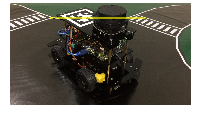

detectedImg = insertObjectAnnotation(img,"Rectangle",bboxes,labels);
figure
imshow(detectedImg)

Calculation of Bounding Box area

Probability = transpose(scores);
width = bboxes(:,3);
length = bboxes(:,4);
Area_box = width .* length;

[Max,Index] = max(Area_box);

label = transpose(labels);
closest_label = label(Index);

disp(closest_label)

     truck 



disp(Probability(Index))

    0.7845



disp(Max)

     5820562

